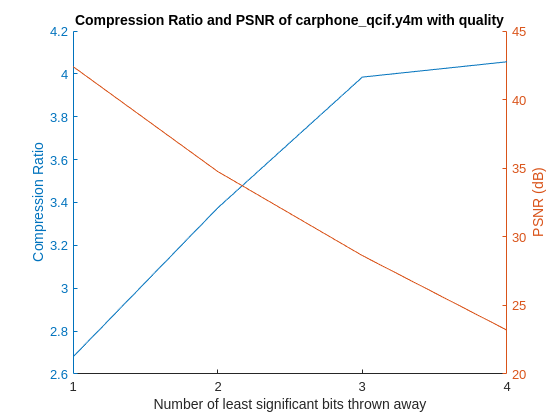

clear;

akiyo_original = 45621044;
bowing_original = 45621044;
carphone_original = 14524448;
city_original = 364957238;
claire_original = 18782912;
football_original = 39538238;

akiyo_frames = 300;
bowing_frames = 300;
carphone_frames = 382;
city_frames = 600;
claire_frames = 494;
football_frames = 260;

x = [1 2 3 4];
carphone_quant = [42.411944 34.762047 28.631429 23.193580];
carphone_quant_s = [5420203 4304060 3644819 3580659];

carphone_times_enc = [10.535 10.485 10.436 10.377];
carphone_times_dec = [0.647 0.506 0.634 0.567];

claire_quant = [40.383717 31.220756 23.599885 18.329309];
claire_quant_s = [4671471 4239869 4070975 4055367];

claire_times_enc = [13.627 13.511 13.449 13.485];
claire_times_dec = [0.701 0.759 0.690 0.680];

cla reset;
hold on;
yyaxis left;
plot(x, carphone_original ./ carphone_quant_s);
xticks(1:4);
title("Compression Ratio and PSNR of carphone\_qcif.y4m (residual quantization)");
xlabel("Number of least significant bits thrown away");
ylabel("Compression Ratio");
yyaxis right;
plot(x, carphone_quant);
ylabel("PSNR (dB)");
hold off;

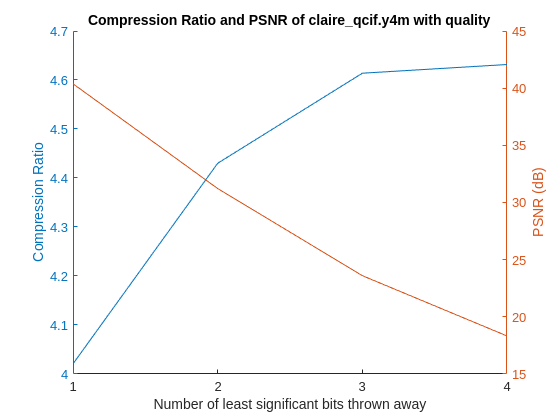


cla reset;
hold on;
yyaxis left;
plot(x, claire_original ./ claire_quant_s);
xticks(1:4);
title("Compression Ratio and PSNR of claire\_qcif.y4m (residual quantization)");
xlabel("Number of least significant bits thrown away");
ylabel("Compression Ratio");
yyaxis right;
plot(x, claire_quant);
ylabel("PSNR (dB)");
hold off;